# Monocular Visual Simultaneous Localization and Mapping

Visual simultaneous localization and mapping (vSLAM), refers to the process of calculating the position and orientation of a camera with respect to its surroundings, while simultaneously mapping the environment. The process uses only visual inputs from the camera. Applications for vSLAM include augmented reality, robotics, and autonomous driving.

There are two versions of vSLAM implementations shown in the examples:

- **Modular and Modifiable **─ Builds a visual SLAM pipeline step-by-step by using functions and objects. For more details and a list of these functions and objects, see the [Implement Visual SLAM in MATLAB](docid:vision_ug#mw_b29d21ad-831b-4434-be26-6ef2ea144561) topic. The approach described in the topic contains modular code and it is designed to teach the details of the vSLAM implementation, which is loosely based on the popular and reliable ORB-SLAM [1] algorithm. The code is easily navigable, allowing you to understand the algorithm and test how its parameters can impact the performance of the system. This modular implementation is most suitable for learning, experimentation, and modification to test your own ideas. 

- **Performant and Deployable** ─ Uses the monovslam object which contains a complete vSLAM workflow. The object offers a practical solution with greatly improved execution speed and code generation. To generate multi-threaded C/C++ code from [`monovslam`](docid:vision_ref#mw_43ffdccf-bf66-4d77-95bf-e86c86b2c64b), you can use MATLAB Coder. The generated code is portable and can also be deployed on non-PC hardware as well as a ROS node as demonstrated in the [Build and Deploy Visual SLAM Algorithm with ROS in MATLAB](docid:vision_ug#mw_13c763a3-acf0-49fc-85dc-b2cdf8c7dfad) example.

This example shows the Modular and Modifiable implementation. For more details about the Performant and Deployable implementation, see the [Performant and Deployable Monocular Visual SLAM](docid:vision_ug#mw_0fecd517-7820-4d71-ad11-cfd167c29f4d) example.

To speed up computations, you can enable parallel computing from the[ Computer Vision Toolbox Preferences](docid:vision_gs#bugsb2y-1) dialog box. To open Computer Vision Toolbox™ preferences, on the **Home** tab, in the **Environment** section, click **Preferences**. Then select **Computer Vision Toolbox. **

## Glossary

The following terms are frequently used in this example:

- **Key Frames:** A subset of video frames that contain cues for localization and tracking. Two consecutive key frames usually involve sufficient visual change.

- **Map Points: **A list of 3-D points that represent the map of the environment reconstructed from the key frames.

- **Covisibility Graph**: A graph consisting of key frame as nodes. Two key frames are connected by an edge if they share common map points. The weight of an edge is the number of shared map points.

- **Essential Graph:** A subgraph of covisibility graph containing only edges with high weight, i.e. more shared map points.

- **Place Recognition Database: **A database used to recognize whether a place has been visited in the past. The database stores the visual word-to-image mapping based on the input bag of features. It is used to search for an image that is visually similar to a query image. 

## Overview of ORB-SLAM

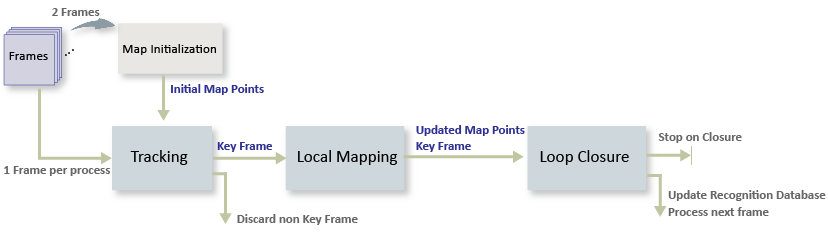

The ORB-SLAM pipeline includes:

- **Map Initialization**: ORB-SLAM starts by initializing the map of 3-D points from two video frames. The 3-D points and relative camera pose are computed using triangulation based on 2-D ORB feature correspondences. 

- **Tracking**: Once a map is initialized, for each new frame, the camera pose is estimated by matching features in the current frame to features in the last key frame. The estimated camera pose is refined by tracking the local map.

- **Local Mapping**: The current frame is used to create new 3-D map points if it is identified as a key frame. At this stage, bundle adjustment is used to minimize reprojection errors by adjusting the camera pose and 3-D points.  

- **Loop Closure**: Loops are detected for each key frame by comparing it against all previous key frames using the bag-of-features approach. Once a loop closure is detected, the pose graph is optimized to refine the camera poses of all the key frames.

## Download and Explore the Input Image Sequence

The data used in this example are from the [TUM RGB-D benchmark](https://cvg.cit.tum.de/data/datasets/rgbd-dataset) [2]. You can download the data to a temporary directory using a web browser or by running the following code:

baseDownloadURL = "https://cvg.cit.tum.de/rgbd/dataset/freiburg3/rgbd_dataset_freiburg3_long_office_household.tgz"; 
dataFolder      = fullfile(tempdir, 'tum_rgbd_dataset', filesep); 
options         = weboptions(Timeout=Inf);
tgzFileName     = [dataFolder, 'fr3_office.tgz'];
folderExists    = exist(dataFolder, "dir");

% Create a folder in a temporary directory to save the downloaded file
if ~folderExists  
    mkdir(dataFolder); 
    disp('Downloading fr3_office.tgz (1.38 GB). This download can take a few minutes.') 
    websave(tgzFileName, baseDownloadURL, options); 

    % Extract contents of the downloaded file
    disp('Extracting fr3_office.tgz (1.38 GB) ...') 
    untar(tgzFileName, dataFolder); 
end

Create an [`imageDatastore`](docid:matlab_ref#butueui-1) object to inspect the RGB images.

imageFolder   = [dataFolder,'rgbd_dataset_freiburg3_long_office_household/rgb/'];
imds          = imageDatastore(imageFolder);

% Inspect the first image
currFrameIdx = 1;
currI = readimage(imds, currFrameIdx);
himage = imshow(currI);

## **Map Initialization**

The ORB-SLAM pipeline starts by initializing the map that holds 3-D world points. This step is crucial and has a significant impact on the accuracy of final SLAM result. Initial ORB feature point correspondences are found using [`matchFeatures`](docid:vision_ref#bsvbhh1-1) between a pair of images. After the correspondences are found, two geometric transformation models are used to establish map initialization:

- **Homography**: If the scene is planar, a homography projective transformation is a better choice to describe feature point correspondences. 

- **Fundamental Matrix:** If the scene is non-planar, a fundamental matrix must be used instead.

The model that results in a smaller reprojection error is selected to estimate the relative rotation and translation between the two frames using [`estrelpose`](docid:vision_ref#mw_839e96cc-f499-4cbb-8c26-4df25c958dc9). Since the RGB images are taken by a monocular camera which does not provide the depth information, the relative translation can only be recovered up to a specific scale factor.    

Given the relative camera pose and the matched feature points in the two images, the 3-D locations of the matched points are determined using [`triangulate`](docid:vision_ref#buefm11-1) function. A triangulated map point is valid when it is located in the front of both cameras, when its reprojection error is low, and when the parallax of the two views of the point is sufficiently large.

% Set random seed for reproducibility
rng(0);

% Create a cameraIntrinsics object to store the camera intrinsic parameters.
% The intrinsics for the dataset can be found at the following page:
% https://vision.in.tum.de/data/datasets/rgbd-dataset/file_formats
% Note that the images in the dataset are already undistorted, hence there
% is no need to specify the distortion coefficients.
focalLength    = [535.4, 539.2];    % in units of pixels
principalPoint = [320.1, 247.6];    % in units of pixels
imageSize      = size(currI,[1 2]);  % in units of pixels
intrinsics     = cameraIntrinsics(focalLength, principalPoint, imageSize);

% Detect and extract ORB features
scaleFactor = 1.2;
numLevels   = 8;
numPoints   = 1000;
[preFeatures, prePoints] = helperDetectAndExtractFeatures(currI, scaleFactor, numLevels, numPoints); 

currFrameIdx = currFrameIdx + 1;
firstI       = currI; % Preserve the first frame 

isMapInitialized  = false;

% Map initialization loop
while ~isMapInitialized && currFrameIdx < numel(imds.Files)
    currI = readimage(imds, currFrameIdx);

    [currFeatures, currPoints] = helperDetectAndExtractFeatures(currI, scaleFactor, numLevels, numPoints); 

    currFrameIdx = currFrameIdx + 1;

    % Find putative feature matches
    indexPairs = matchFeatures(preFeatures, currFeatures, Unique=true, ...
        MaxRatio=0.9, MatchThreshold=40);

    % If not enough matches are found, check the next frame
    minMatches = 100;
    if size(indexPairs, 1) < minMatches
        continue
    end

    preMatchedPoints  = prePoints(indexPairs(:,1),:);
    currMatchedPoints = currPoints(indexPairs(:,2),:);

    % Compute homography and evaluate reconstruction
    [tformH, scoreH, inliersIdxH] = helperComputeHomography(preMatchedPoints, currMatchedPoints);

    % Compute fundamental matrix and evaluate reconstruction
    [tformF, scoreF, inliersIdxF] = helperComputeFundamentalMatrix(preMatchedPoints, currMatchedPoints, intrinsics);

    % Select the model based on a heuristic
    ratio = scoreH/(scoreH + scoreF);
    ratioThreshold = 0.45;
    if ratio > ratioThreshold
        inlierTformIdx = inliersIdxH;
        tform          = tformH;
    else
        inlierTformIdx = inliersIdxF;
        tform          = tformF;
    end

    % Computes the camera location up to scale. Use half of the 
    % points to reduce computation
    inlierPrePoints  = preMatchedPoints(inlierTformIdx);
    inlierCurrPoints = currMatchedPoints(inlierTformIdx);
    [relPose, validFraction] = estrelpose(tform, intrinsics, ...
        inlierPrePoints(1:2:end), inlierCurrPoints(1:2:end));

    % If not enough inliers are found, move to the next frame
    if validFraction < 0.9 || numel(relPose)>1
        continue
    end

    % Triangulate two views to obtain 3-D map points
    minParallax = 1; % In degrees
    [isValid, xyzWorldPoints, inlierTriangulationIdx] = helperTriangulateTwoFrames(...
        rigidtform3d, relPose, inlierPrePoints, inlierCurrPoints, intrinsics, minParallax);

    if ~isValid
        continue
    end

    % Get the original index of features in the two key frames
    indexPairs = indexPairs(inlierTformIdx(inlierTriangulationIdx),:);

    isMapInitialized = true;

    disp(['Map initialized with frame 1 and frame ', num2str(currFrameIdx-1)])
end % End of map initialization loop

Map initialized with frame 1 and frame 30


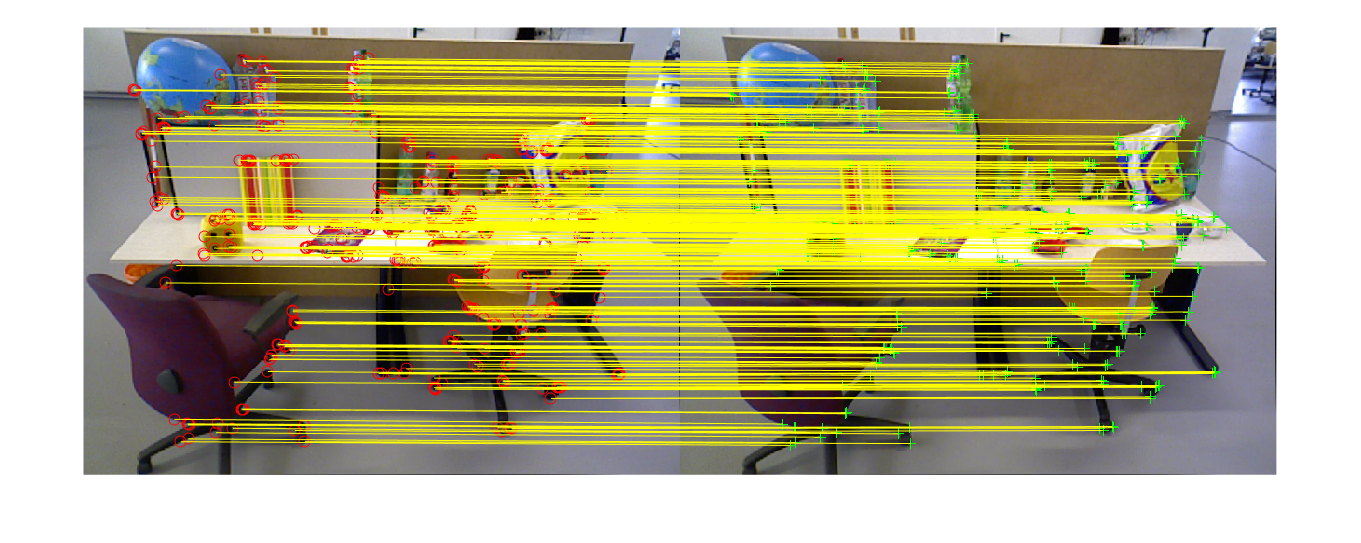


if isMapInitialized
    close(himage.Parent.Parent); % Close the previous figure
    % Show matched features
    hfeature = showMatchedFeatures(firstI, currI, prePoints(indexPairs(:,1)), ...
        currPoints(indexPairs(:, 2)), "Montage");
else
    error('Unable to initialize the map.')
end

## Store Initial Key Frames and Map Points

After the map is initialized using two frames, you can use [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78) and [`worldpointset`](docid:vision_ref#mw_3d5c7b4a-5b50-436d-a8b0-f20fc3d7a466) to store the two key frames and the corresponding map points:

- [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78) stores the key frames and their attributes, such as ORB descriptors, feature points and camera poses, and connections between the key frames, such as feature points matches and relative camera poses. It also builds and updates a pose graph. The absolute camera poses and relative camera poses of odometry edges are stored as [`rigidtform3d`](docid:images_ref#mw_ac5763d9-ceb0-44c0-85af-41d437cc74b4) objects. The relative camera poses of loop-closure edges are stored as [`affinetform3d`](docid:images_ref#mw_40291f8c-2edc-4b5f-90be-775bb40a8a9f) objects.

- [`worldpointset`](docid:vision_ref#mw_3d5c7b4a-5b50-436d-a8b0-f20fc3d7a466) stores 3-D positions of the map points and the 3-D into 2-D projection correspondences: which map points are observed in a key frame and which key frames observe a map point. It also stores other attributes of map points, such as the mean view direction, the representative ORB descriptors, and the range of distance at which the map point can be observed.

% Create an empty imageviewset object to store key frames
vSetKeyFrames = imageviewset;

% Create an empty worldpointset object to store 3-D map points
mapPointSet   = worldpointset;

% Add the first key frame. Place the camera associated with the first 
% key frame at the origin, oriented along the Z-axis
preViewId     = 1;
vSetKeyFrames = addView(vSetKeyFrames, preViewId, rigidtform3d, Points=prePoints,...
    Features=preFeatures.Features);

% Add the second key frame
currViewId    = 2;
vSetKeyFrames = addView(vSetKeyFrames, currViewId, relPose, Points=currPoints,...
    Features=currFeatures.Features);

% Add connection between the first and the second key frame
vSetKeyFrames = addConnection(vSetKeyFrames, preViewId, currViewId, relPose, Matches=indexPairs);

% Add 3-D map points
[mapPointSet, newPointIdx] = addWorldPoints(mapPointSet, xyzWorldPoints);

% Add image points corresponding to the map points in the first key frame
mapPointSet   = addCorrespondences(mapPointSet, preViewId, newPointIdx, indexPairs(:,1));

% Add image points corresponding to the map points in the second key frame
mapPointSet   = addCorrespondences(mapPointSet, currViewId, newPointIdx, indexPairs(:,2));


## Initialize Place Recognition Database

Loop detection is performed using the bags-of-words approach.  A visual vocabulary represented as a `bagOfFeaturesDBoW` object is created offline with the ORB descriptors extracted from a large set of images in the dataset by calling:

`bag = bagOfFeaturesDBoW(imds);`

where `imds` is an [`imageDatastore`](docid:matlab_ref#butueui-1) object storing the training images.

The loop closure process incrementally builds a database, represented as an `dbowLoopDetector` object, that stores the visual word-to-image mapping based on the bag of ORB features.

% Load the bag of features data created offline
bag         = bagOfFeaturesDBoW("bagOfFeatures.bin.gz");

% Initialize the place recognition database
loopDatabase    = dbowLoopDetector(bag);

% Add features of the first two key frames to the database
addVisualFeatures(loopDatabase, preViewId, preFeatures);
addVisualFeatures(loopDatabase, currViewId, currFeatures);

## Refine and Visualize the Initial Reconstruction

Refine the initial reconstruction using [`bundleAdjustment`](docid:vision_ref#bu48f97-1), that optimizes both camera poses and world points to minimize the overall reprojection errors. After the refinement, the attributes of the map points including 3-D locations, view direction, and depth range are updated. You can use [`helperVisualizeMotionAndStructure`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperVisualizeMotionAndStructure.m')) to visualize the map points and the camera locations. 

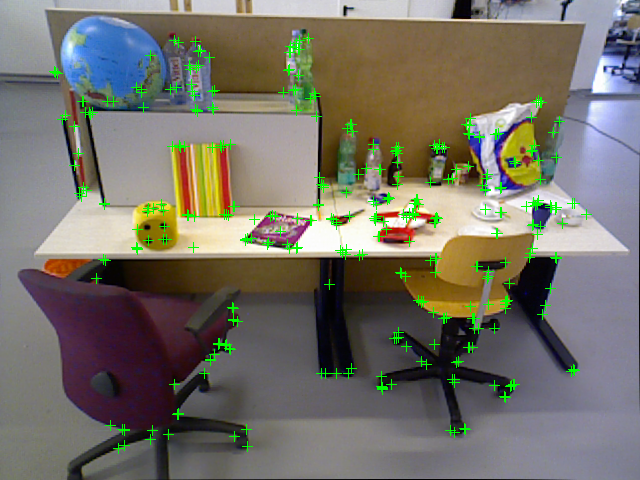

% Run full bundle adjustment on the first two key frames
tracks       = findTracks(vSetKeyFrames);
cameraPoses  = poses(vSetKeyFrames);

[refinedPoints, refinedAbsPoses] = bundleAdjustment(xyzWorldPoints, tracks, ...
    cameraPoses, intrinsics, FixedViewIDs=1, ...
    PointsUndistorted=true, AbsoluteTolerance=1e-7,...
    RelativeTolerance=1e-15, MaxIteration=20, ...
    Solver="preconditioned-conjugate-gradient");

% Scale the map and the camera pose using the median depth of map points
medianDepth   = median(vecnorm(refinedPoints.'));
refinedPoints = refinedPoints / medianDepth;

refinedAbsPoses.AbsolutePose(currViewId).Translation = ...
    refinedAbsPoses.AbsolutePose(currViewId).Translation / medianDepth;
relPose.Translation = relPose.Translation/medianDepth;

% Update key frames with the refined poses
vSetKeyFrames = updateView(vSetKeyFrames, refinedAbsPoses);
vSetKeyFrames = updateConnection(vSetKeyFrames, preViewId, currViewId, relPose);

% Update map points with the refined positions
mapPointSet = updateWorldPoints(mapPointSet, newPointIdx, refinedPoints);

% Update view direction and depth 
mapPointSet = updateLimitsAndDirection(mapPointSet, newPointIdx, vSetKeyFrames.Views);

% Update representative view
mapPointSet = updateRepresentativeView(mapPointSet, newPointIdx, vSetKeyFrames.Views);

% Visualize matched features in the current frame
close(hfeature.Parent.Parent);
featurePlot   = helperVisualizeMatchedFeatures(currI, currPoints(indexPairs(:,2)));

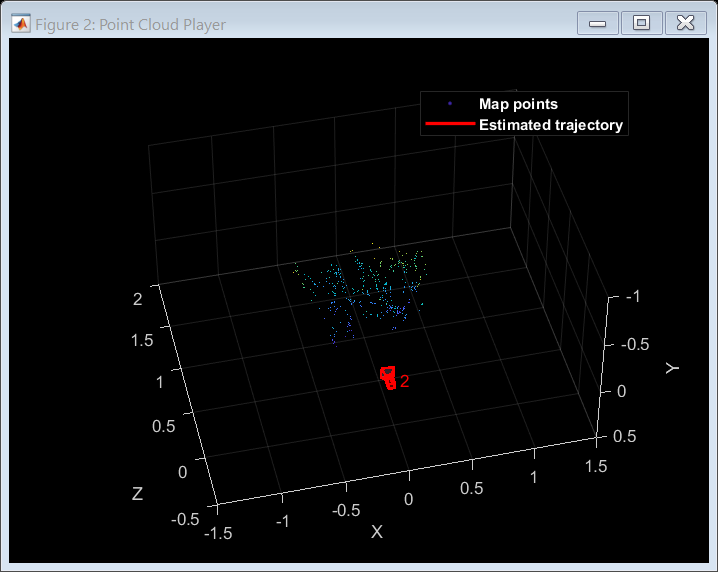


% Visualize initial map points and camera trajectory
mapPlot       = helperVisualizeMotionAndStructure(vSetKeyFrames, mapPointSet);

% Show legend
showLegend(mapPlot);

## Tracking

The tracking process is performed using every frame and determines when to insert a new key frame. 

% ViewId of the current key frame
currKeyFrameId   = currViewId;

% ViewId of the last key frame
lastKeyFrameId   = currViewId;

% Index of the last key frame in the input image sequence
lastKeyFrameIdx  = currFrameIdx - 1; 

% Indices of all the key frames in the input image sequence
addedFramesIdx   = [1; lastKeyFrameIdx];

isLoopClosed     = false;

Each frame is processed as follows:

- ORB features are extracted for each new frame and then matched with features in the last key frame that have known corresponding 3-D map points. Assuming a linear camera motion model, the expected matched locations in the current frame that correspond to the feature points from the last key frame can be predicted using [`vision.PointTracker`](docid:vision_ref#btghk3u-1).

- With 3-D to 2-D correspondence in the current frame, estimate the camera pose with the Perspective-n-Point algorithm using [`estworldpose`](docid:vision_ref#mw_9685837b-561a-4e27-a7c5-0e1ac2d32fd8) and refine the camera pose by performing a motion-only bundle adjustment using [`bundleAdjustmentMotion`](docid:vision_ref#mw_11887bed-7a1c-44d8-929a-e5401685ddcf). 

- Project the local map points into the current frame to search for more feature correspondences using [`matchFeaturesInRadius`](https://www.mathworks.com/help/vision/ref/matchfeaturesinradius.html) and refine the camera pose again using [`bundleAdjustmentMotion`](https://www.mathworks.com/help/vision/ref/bundleadjustmentmotion.html).

- The last step of tracking is to decide if the current frame is a new key frame. If the current frame is a key frame, continue to the **Local Mapping **process. Otherwise, start **Tracking** for the next frame. 

If tracking is lost because not enough number of feature points could be matched, try inserting new key frames more frequently.

Loop edge added between keyframe: 5 and 129
Loop edge added between keyframe: 5 and 130
Loop edge added between keyframe: 6 and 131
Loop edge added between keyframe: 6 and 144
Loop edge added between keyframe: 3 and 145
Loop edge added between keyframe: 5 and 146


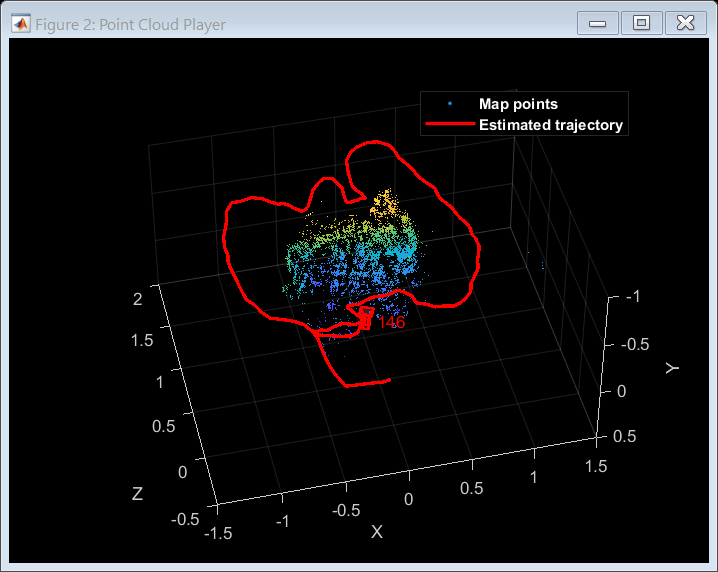

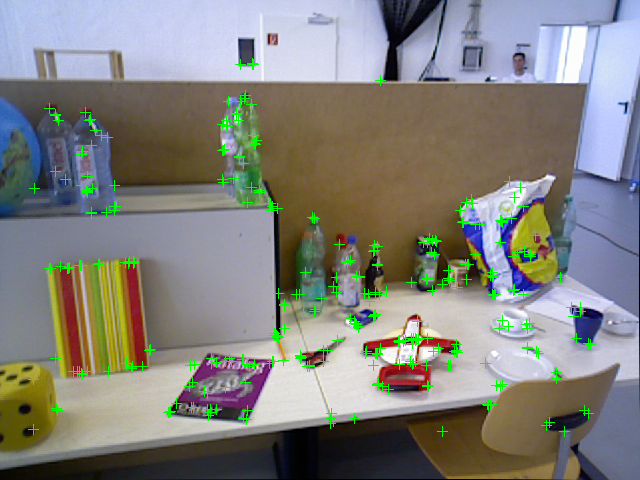

% Main loop
isLastFrameKeyFrame = true;

% Create and initialize the KLT tracker
tracker = vision.PointTracker(MaxBidirectionalError = 5);
initialize(tracker, currPoints.Location(indexPairs(:,2), :), currI);

while currFrameIdx < numel(imds.Files)  
    currI = readimage(imds, currFrameIdx);
    [currFeatures, currPoints] = helperDetectAndExtractFeatures(currI, scaleFactor, numLevels, numPoints);

    % Track the last key frame
    [currPose, mapPointsIdx, featureIdx] = helperTrackLastKeyFrameKLT(tracker, currI, mapPointSet, ...
        vSetKeyFrames.Views, currFeatures, currPoints, lastKeyFrameId, intrinsics);

    % Track the local map and check if the current frame is a key frame.
    % A frame is a key frame if both of the following conditions are satisfied:
    %
    % 1. At least 20 frames have passed since the last key frame or the
    %    current frame tracks fewer than 100 map points.
    % 2. The map points tracked by the current frame are fewer than 90% of
    %    points tracked by the reference key frame.
    %
    % Tracking performance is sensitive to the value of numPointsKeyFrame.  
    % If tracking is lost, try a larger value.
    %
    % localKeyFrameIds:   ViewId of the connected key frames of the current frame
    numSkipFrames     = 20;
    numPointsKeyFrame = 90;
    [localKeyFrameIds, currPose, mapPointsIdx, featureIdx, isKeyFrame] = ...
        helperTrackLocalMap(mapPointSet, vSetKeyFrames, mapPointsIdx, ...
        featureIdx, currPose, currFeatures, currPoints, intrinsics, scaleFactor, ...
        isLastFrameKeyFrame, lastKeyFrameIdx, currFrameIdx, numSkipFrames, numPointsKeyFrame);

    % Visualize matched features
    updatePlot(featurePlot, currI, currPoints(featureIdx));

    if ~isKeyFrame
        currFrameIdx        = currFrameIdx + 1;
        isLastFrameKeyFrame = false;
        continue
    else
        currKeyFrameId      = currKeyFrameId + 1;
        isLastFrameKeyFrame = true;
    end

## Local Mapping

Local mapping is performed for every key frame. When a new key frame is determined, add it to the key frames and update the attributes of the map points observed by the new key frame. To ensure that `mapPointSet` contains as few outliers as possible, a valid map point must be observed in at least 3 key frames. 

New map points are created by triangulating ORB feature points in the current key frame and its connected key frames. For each unmatched feature point in the current key frame, search for a match with other unmatched points in the connected key frames using [`matchFeatures`](docid:vision_ref#bsvbhh1-1). The local bundle adjustment refines the pose of the current key frame, the poses of connected key frames, and all the map points observed in these key frames.

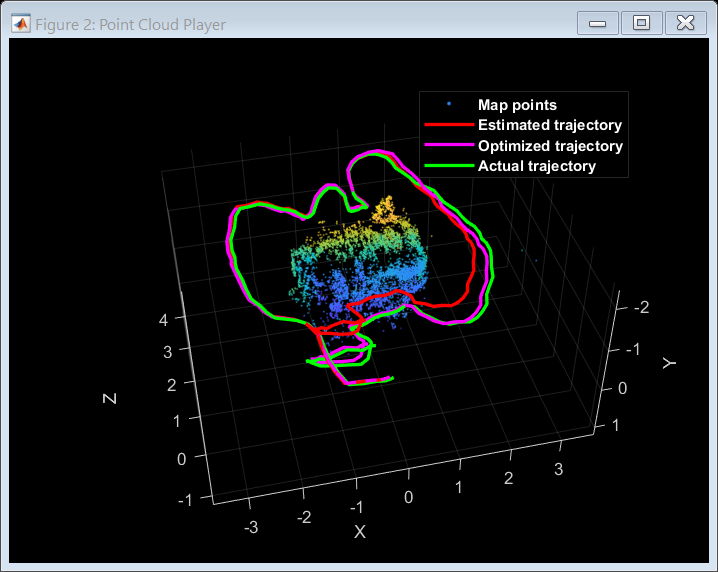

    % Add the new key frame 
    [mapPointSet, vSetKeyFrames] = helperAddNewKeyFrame(mapPointSet, vSetKeyFrames, ...
        currPose, currFeatures, currPoints, mapPointsIdx, featureIdx, localKeyFrameIds);

    % Remove outlier map points that are observed in fewer than 3 key frames
    outlierIdx    = setdiff(newPointIdx, mapPointsIdx);
    if ~isempty(outlierIdx)
        mapPointSet   = removeWorldPoints(mapPointSet, outlierIdx);
    end

    % Create new map points by triangulation
    minNumMatches = 10;
    minParallax   = 3;
    [mapPointSet, vSetKeyFrames, newPointIdx] = helperCreateNewMapPoints(mapPointSet, vSetKeyFrames, ...
        currKeyFrameId, intrinsics, scaleFactor, minNumMatches, minParallax);

    % Local bundle adjustment
    [refinedViews, dist] = connectedViews(vSetKeyFrames, currKeyFrameId, MaxDistance=2);
    refinedKeyFrameIds = refinedViews.ViewId;
    fixedViewIds = refinedKeyFrameIds(dist==2);
    fixedViewIds = fixedViewIds(1:min(10, numel(fixedViewIds)));

    % Refine local key frames and map points
    [mapPointSet, vSetKeyFrames, mapPointIdx] = bundleAdjustment(...
        mapPointSet, vSetKeyFrames, [refinedKeyFrameIds; currKeyFrameId], intrinsics, ...
        FixedViewIDs=fixedViewIds, PointsUndistorted=true, AbsoluteTolerance=1e-7,...
        RelativeTolerance=1e-16, Solver="preconditioned-conjugate-gradient", ...
        MaxIteration=10);

    % Update view direction and depth
    mapPointSet = updateLimitsAndDirection(mapPointSet, mapPointIdx, vSetKeyFrames.Views);

    % Update representative view
    mapPointSet = updateRepresentativeView(mapPointSet, mapPointIdx, vSetKeyFrames.Views);


Absolute RMSE for key frame location (m): 0.086973


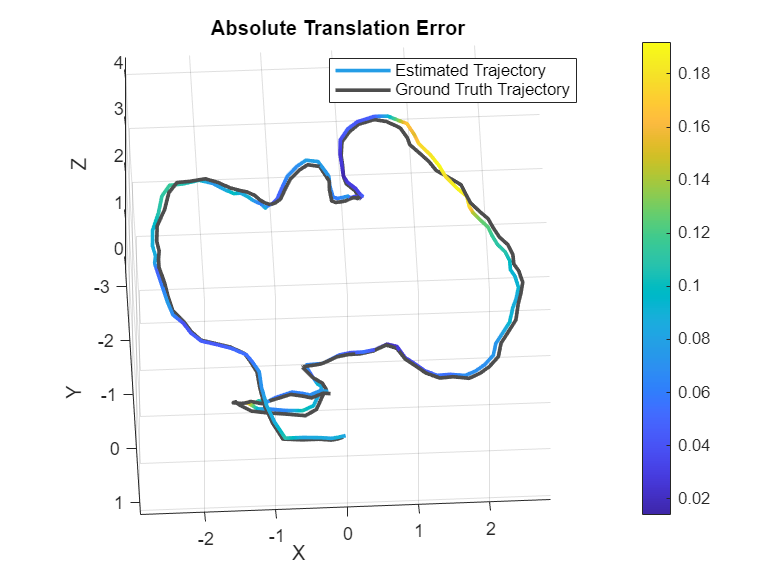

    % Visualize 3D world points and camera trajectory
    updatePlot(mapPlot, vSetKeyFrames, mapPointSet);

    % Set the feature points to be tracked
    [~, index2d] = findWorldPointsInView(mapPointSet, currKeyFrameId);
    setPoints(tracker, currPoints.Location(index2d, :));

## Loop Closure

The loop closure detection step takes the current key frame processed by the local mapping process and tries to detect and close the loop.  Loop candidates are identified by querying images in the database that are visually similar to the current key frame using [`evaluateImageRetrieval`](docid:vision_ref#bumxi3p-1). A candidate key frame is valid if it is not connected to the last key frame and three of its neighbor key frames are loop candidates. 

When a valid loop candidate is found, use [`estgeotform3d`](docid:vision_ref#mw_2e99afb0-9afd-4353-8f9e-9de2e40ee066) to compute the relative pose between the loop candidate frame and the current key frame. The relative pose represents a 3-D similarity transformation stored in an `simtform3d` object. Then add the loop connection with the relative pose and update `mapPointSet `and `vSetKeyFrames`.

    % Check loop closure after some key frames have been created    
    if currKeyFrameId > 20

        % Minimum number of feature matches of loop edges
        loopEdgeNumMatches = 50;

        % Detect possible loop closure key frame candidates
        [isDetected, validLoopCandidates] = helperCheckLoopClosure(vSetKeyFrames, currKeyFrameId, ...
            loopDatabase, currFeatures, loopEdgeNumMatches);


Code generation successful.



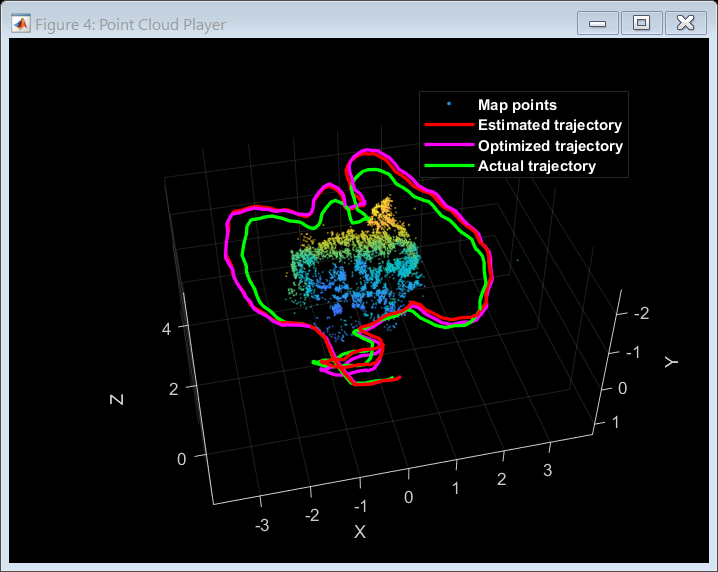

        if isDetected 
            % Add loop closure connections
            [isLoopClosed, mapPointSet, vSetKeyFrames] = helperAddLoopConnections(...
                mapPointSet, vSetKeyFrames, validLoopCandidates, currKeyFrameId, ...
                currFeatures, loopEdgeNumMatches);
        end

    end

    % If no loop closure is detected, add current features into the database
    if ~isLoopClosed
        addVisualFeatures(loopDatabase,  currKeyFrameId, currFeatures);
    end

    % Update IDs and indices
    lastKeyFrameId  = currKeyFrameId;
    lastKeyFrameIdx = currFrameIdx;
    addedFramesIdx  = [addedFramesIdx; currFrameIdx]; %#ok<AGROW>
    currFrameIdx    = currFrameIdx + 1;
end % End of main loop

Finally, a similarity pose graph optimization is performed over the essential graph in `vSetKeyFrames `to correct the drift of camera poses. The essential graph is created internally by removing connections with fewer than `minNumMatches `matches in the covisibility graph. After similarity pose graph optimization, update the 3-D locations of the map points using the optimized poses and the associated scales.

if isLoopClosed
    % Optimize the poses
    minNumMatches      = 30;
    vSetKeyFramesOptim = optimizePoses(vSetKeyFrames, minNumMatches, Tolerance=1e-16);

    % Update map points after optimizing the poses
    mapPointSet = helperUpdateGlobalMap(mapPointSet, vSetKeyFrames, vSetKeyFramesOptim);

    updatePlot(mapPlot, vSetKeyFrames, mapPointSet);

    % Plot the optimized camera trajectory
    optimizedPoses  = poses(vSetKeyFramesOptim);
    plotOptimizedTrajectory(mapPlot, optimizedPoses)

    % Update legend
    showLegend(mapPlot);
end

## Compare with the Ground Truth

You can compare the optimized camera trajectory with the ground truth to evaluate the accuracy of ORB-SLAM. The downloaded data contains a `groundtruth.txt` file that stores the ground truth of camera pose of each frame. You can import the data using the [`helperImportGroundTruth`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperImportGroundTruth.m')) function:

`gTruthFileName = [dataFolder,'rgbd_dataset_freiburg3_long_office_household/groundtruth.txt'];`

`gTruth = helperImportGroundTruth(gTruthFileName, imds);`

In this example, the data has been saved in the form of a MAT-file. Once the ground truth is imported, you can calculate the root-mean-square-error (RMSE) of trajectory estimates. 

if isLoopClosed

    % Load ground truth
    gTruthData = load("orbslamGroundTruth.mat");
    gTruth     = gTruthData.gTruth;

    % Plot the actual camera trajectory
    plotActualTrajectory(mapPlot, gTruth(addedFramesIdx), optimizedPoses);

    % Show legend
    showLegend(mapPlot);
end

if isLoopClosed

    % Evaluate tracking accuracy
    errorMetrics = compareTrajectories(optimizedPoses.AbsolutePose, gTruth(addedFramesIdx), AlignmentType="similarity");
    disp(['Absolute RMSE for key frame location (m): ', num2str(errorMetrics.AbsoluteRMSE(2))]);
    % Plot the absolute translation error at each key frame
    figure
    ax = plot(errorMetrics, "absolute-translation");

    % Adjust the view
    view(ax, [2.70 -49.20]);
end

You can test the visual SLAM pipeline with a different dataset by tuning the following parameters:

- `numPoints`: For image resolution of 480x640 pixels set `numPoints` to be 1000. For higher resolutions, such as 720 × 1280, set it to 2000. Larger values require more time in feature extraction.

- `numSkipFrames`: For frame rate of 30fps, set `numSkipFrames` to be 20. For a slower frame rate, set it to be a smaller value. Increasing `numSkipFrames `improves the tracking speed, but may result in tracking lost when the camera motion is fast.

## Code Generation

To meet the requirements of MATLAB Coder, the above code is restructured to the entry-point function [`helperVisualSLAMCodegen`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperVisualSLAMCodegen.m')). This function takes a cell array of images as an input and outputs 3-D [`worldpoints`](docid:vision_ref#mw_3d5c7b4a-5b50-436d-a8b0-f20fc3d7a466), estimated camera poses, and frame indices.

As code generation does not support the [`imageDatastore`](docid:matlab_ref#butueui-1) object, read the images, convert them to grayscale, and store them in a cell array.

imageArray = cell(1,numel(imds.Files));
for i = 1:numel(imds.Files)
    imageArray{i} = im2gray(readimage(imds,i));
end

Use the [`codegen`](docid:coder_ug#brdqzuf) function to compile the [`helperVisualSLAMCodegen`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperVisualSLAMCodegen.m')) function into a MEX file. You can specify the `-report` option to generate a compilation report that shows the original MATLAB code and the associated files created during code generation. You can also create a temporary directory where MATLAB Coder can store the generated files. Note that, by default, the generated MEX file has the same name as the original MATLAB function with "`_mex"` appended as a suffix: `helperVisualSLAMCodegen_mex`. Alternatively, you can use the `-o` option to specify the name of the MEX file.

For code generation, you must pass `imageArray` as an input to the [`helperVisualSLAMCodegen`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperVisualSLAMCodegen.m')) function.

cpuConfig = coder.config("mex");
cpuConfig.TargetLang = "C++";
codegen -config cpuConfig helperVisualSLAMCodegen -args {imageArray}

Process the image data using the MEX-file.

monoSlamOut = helperVisualSLAMCodegen_mex(imageArray);

Plot the estimated trajectory and actual trajectory of the camera by specifying `monoSlamOut` as an input argument to the [`helperVisualizeMonoSlam`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperVisualizeMonoSlam.m')) helper function.

% Visualize the results
mapPlot = helperVisualizeMonoVisualSlam(monoSlamOut);

## Supporting Functions

Short helper functions are included below. Larger function are included in separate files.

[`helperAddLoopConnections`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperAddLoopConnections.m')) add connections between the current keyframe and the valid loop candidate.

[`helperAddNewKeyFrame`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperAddNewKeyFrame.m')) add key frames to the key frame set.

[`helperCheckLoopClosure`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperCheckLoopClosure.m')) detect loop candidates key frames by retrieving visually similar images from the database.

[`helperCreateNewMapPoints`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperCreateNewMapPoints.m')) create new map points by triangulation.

[`helperORBFeatureExtractorFunction`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperORBFeatureExtractorFunction.m')) implements the ORB feature extraction used in bagOfFeatures.

[`helperTrackLastKeyFrameKLT`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperTrackLastKeyFrameKLT.m')) estimate the current camera pose by tracking the last key frame using the KLT tracker.

[`helperTrackLocalMap`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperTrackLocalMap.m')) refine the current camera pose by tracking the local map.

[`helperVisualizeMatchedFeatures`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperVisualizeMatchedFeatures.m')) show the matched features in a frame.

[`helperVisualizeMotionAndStructure`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperVisualizeMotionAndStructure.m')) show map points and camera trajectory.

[`helperImportGroundTruth`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperImportGroundTruth.m')) import camera pose ground truth from the downloaded data.

`helperDetectAndExtractFeatures` detect and extract and ORB features from the image.

function [features, validPoints] = helperDetectAndExtractFeatures(Irgb, ...
    scaleFactor, numLevels, numPoints, varargin)

% In this example, the images are already undistorted. In a general
% workflow, uncomment the following code to undistort the images.
%
% if nargin > 4
%     intrinsics = varargin{1};
% end
% Irgb  = undistortImage(Irgb, intrinsics);

% Detect ORB features
Igray  = im2gray(Irgb);

points = detectORBFeatures(Igray, ScaleFactor=scaleFactor, NumLevels=numLevels);

% Select a subset of features, uniformly distributed throughout the image
points = selectUniform(points, numPoints, size(Igray, 1:2));

% Extract features
[features, validPoints] = extractFeatures(Igray, points);
end

`helperComputeHomography `compute homography and evaluate reconstruction.

function [H, score, inliersIndex] = helperComputeHomography(matchedPoints1, matchedPoints2)

[H, inliersLogicalIndex] = estgeotform2d( ...
    matchedPoints1, matchedPoints2, "projective", ...
    MaxNumTrials=1e3, MaxDistance=4);

inlierPoints1 = matchedPoints1(inliersLogicalIndex);
inlierPoints2 = matchedPoints2(inliersLogicalIndex);

inliersIndex  = find(inliersLogicalIndex);

locations1 = inlierPoints1.Location;
locations2 = inlierPoints2.Location;
xy1In2     = transformPointsForward(H, locations1);
xy2In1     = transformPointsInverse(H, locations2);
error1in2  = sum((locations2 - xy1In2).^2, 2);
error2in1  = sum((locations1 - xy2In1).^2, 2);

outlierThreshold = 6;

score = sum(max(outlierThreshold-error1in2, 0)) + ...
    sum(max(outlierThreshold-error2in1, 0));
end

 `helperFundamentalMatrix `compute fundamental matrix and evaluate reconstruction.

function [F, score, inliersIndex] = helperComputeFundamentalMatrix(matchedPoints1, matchedPoints2, intrinsics)

[E, inliersLogicalIndex] = estimateEssentialMatrix( ...
    matchedPoints1, matchedPoints2, intrinsics, MaxNumTrials=1e3, MaxDistance=4);

F = intrinsics.K'\ E /intrinsics.K;

inlierPoints1 = matchedPoints1(inliersLogicalIndex);
inlierPoints2 = matchedPoints2(inliersLogicalIndex);

inliersIndex  = find(inliersLogicalIndex);

locations1    = inlierPoints1.Location;
locations2    = inlierPoints2.Location;

% Distance from points to epipolar line
lineIn1   = epipolarLine(F', locations2);
error2in1 = (sum([locations1, ones(size(locations1, 1),1)].* lineIn1, 2)).^2 ...
    ./ sum(lineIn1(:,1:2).^2, 2);
lineIn2   = epipolarLine(F, locations1);
error1in2 = (sum([locations2, ones(size(locations2, 1),1)].* lineIn2, 2)).^2 ...
    ./ sum(lineIn2(:,1:2).^2, 2);

outlierThreshold = 4;

score = sum(max(outlierThreshold-error1in2, 0)) + ...
    sum(max(outlierThreshold-error2in1, 0));

end

`helperTriangulateTwoFrames `triangulate two frames to initialize the map.

function [isValid, xyzPoints, inlierIdx] = helperTriangulateTwoFrames(...
    pose1, pose2, matchedPoints1, matchedPoints2, intrinsics, minParallax)

camMatrix1 = cameraProjection(intrinsics, pose2extr(pose1));
camMatrix2 = cameraProjection(intrinsics, pose2extr(pose2));

[xyzPoints, reprojectionErrors, isInFront] = triangulate(matchedPoints1, ...
    matchedPoints2, camMatrix1, camMatrix2);

% Filter points by view direction and reprojection error
minReprojError = 1;
inlierIdx  = isInFront & reprojectionErrors < minReprojError;
xyzPoints  = xyzPoints(inlierIdx ,:);

% A good two-view with significant parallax
ray1       = xyzPoints - pose1.Translation;
ray2       = xyzPoints - pose2.Translation;
cosAngle   = sum(ray1 .* ray2, 2) ./ (vecnorm(ray1, 2, 2) .* vecnorm(ray2, 2, 2));

% Check parallax
isValid = all(cosAngle < cosd(minParallax) & cosAngle>0);
end

`helperUpdateGlobalMap` update 3-D locations of map points after pose graph optimization

function mapPointSet = helperUpdateGlobalMap(...
    mapPointSet, vSetKeyFrames, vSetKeyFramesOptim)
%helperUpdateGlobalMap update map points after pose graph optimization
posesOld     = vSetKeyFrames.Views.AbsolutePose;
posesNew     = vSetKeyFramesOptim.Views.AbsolutePose;
positionsOld = mapPointSet.WorldPoints;
positionsNew = positionsOld;
indices     = 1:mapPointSet.Count;

% Update world location of each map point based on the new absolute pose of 
% the corresponding major view
for i = indices
    majorViewIds = mapPointSet.RepresentativeViewId(i);
    poseNew = posesNew(majorViewIds).A;
    tform = affinetform3d(poseNew/posesOld(majorViewIds).A);
    positionsNew(i, :) = transformPointsForward(tform, positionsOld(i, :));
end
mapPointSet = updateWorldPoints(mapPointSet, indices, positionsNew);
end

## **Reference**

[1] Mur-Artal, Raul, Jose Maria Martinez Montiel, and Juan D. Tardos. "ORB-SLAM: a versatile and accurate monocular SLAM system." *IEEE Transactions on Robotics* 31, no. 5, pp 1147-116, 2015.

[2] Sturm, Jürgen, Nikolas Engelhard, Felix Endres, Wolfram Burgard, and Daniel Cremers. "A benchmark for the evaluation of RGB-D SLAM systems". In *Proceedings of IEEE/RSJ International Conference on Intelligent Robots and Systems*, pp. 573-580, 2012.

[3] Kümmerle, Rainer, Giorgio Grisetti, Hauke Strasdat, Kurt Konolige, and Wolfram Burgard. "g2o: A general framework for graph optimization." In *Proceedings of IEEE International Conference on Robotics and Automation*, pp. 3607-3613, 2011.

*Copyright 2019-2024 The MathWorks, Inc.*